# Discrete physiologically structured model for *Tribolium*

*John Nagy*

*June 2024*

## Introduction

In these notes I'll construct an age-structured model for *Tribolium* to compete with the famous LPA model, largely because the LPA model doesn't represent our data very well. This attempt is one of 2: a discrete-stage model in the form of a nonlinear matrix model, and a continuous PDE model to be constructed in another set of notes. 

At the moment I have a group of students in my QRLSSP program working on precisely this problem. Here I'll construct a very flexible parallel model. In particular, I'll assume that each time step represents a single day, with maturation occuring as described in the LPA model--14 days from egg to non-feeding larva, 14 days from nonfeeding larva to pupa to callow adult, and then adult. Their only other addition, besides the much larger projection matrix, is the assumption that eggs and early instars are susceptible to cannibalism for only their first 3 days (see Fig. 1). 

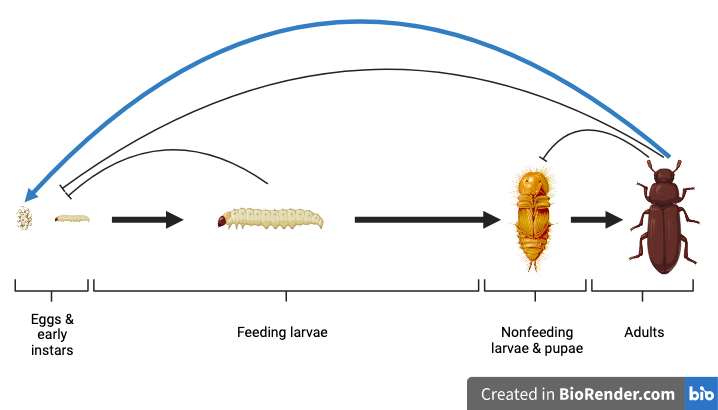

**Figure 1. **Life cycle stages of *Tribolium confusum.*

Here I'll attempt to generalize these assumptions. Here's what I'm thinking.

- Each time step is still a day, and only eggs and early instars can be cannibalized (besides later cannibalism of pupae by adults).

- Complete development from egg to reproductive adult takes $S+1$ days, starting on day 0 and ending on day $S$. 

- Transitions from small instar (defined as being susceptible to predation) to large feeding larva to nonfeeding larva to fully mature, reproductive adult occur on stage days $s_1$, $s_2$, and $S-1$, respectively. Transitions occur on the stage day indicated. For example, a beetle is an egg or early instar from stage 0 to stage $s_1 - 1$, and becomes a feeding larva on stage day $s_1$. For ease of discourse, call stages 0 through $s_1 -1$ the susceptible phase, stages $s_1$ through $s_2 -1$ the larval phase, stages $s_2$ through $S-1$ the pupal phase (even though it contains nonfeeding larvae and callows as well), and stage $S$ the adult phase.

- Beetles in the adult and larval phases consume beetles in the susceptible phase, and adults eat beetles in the pupal phase (Fig. 1).

The main mathematical object we'll study is the state vector, $p(s,n)$, where $p$ is a real-valued vector and $s, n \in \mathbb{Z}$. Specifically, $p(s,t)$ is the number of beetles in stage $s$ at time $t$. In addition, $s$ is restricted to living on the set $\{0, 1, \ldots, S\}$, where $S$ is the adult stage. With this state vector, the model takes the form,

$\mathbf{p}_{n+1} = \mathbf{A} \mathbf{p}_n$,

where $\mathbf{A}$ is the $S+1$ square projection matrix. Here I'll initialize the details of the model:

S = 28;  % Adult developmental stage; default = 29 (14 days larva, 14 days pupa, 1 adult stage)
s1 = 4;  % Stage of transition from susceptible larva to feeding larva
s2 = 14; % Stage of transition from feeding larva to nonfeeding larva

syms p [S+1, 1] 'real'     % Population state vector
assumeAlso(p >= 0);        % State vector cannot be negative
p 

$$p = \left(\begin{array}{c} p_{1}\\ p_{2}\\ p_{3}\\ p_{4}\\ p_{5}\\ p_{6}\\ p_{7}\\ p_{8}\\ p_{9}\\ p_{10}\\ p_{11}\\ p_{12}\\ p_{13}\\ p_{14}\\ p_{15}\\ p_{16}\\ p_{17}\\ p_{18}\\ p_{19}\\ p_{20}\\ p_{21}\\ p_{22}\\ p_{23}\\ p_{24}\\ p_{25}\\ p_{26}\\ p_{27}\\ p_{28}\\ p_{29} \end{array}\right)$$

A = sym(zeros(S+1, S+1));  % Projection matrix

## Construction of the projection matrix

Before I define the projection matrix, I'll need to initialize the parameters. One set of parameters represent the classical LPA values, but for this model I'll have to alter those to match the daily rate. To get the daily natural death rate from the data provided by Dennis et al. and our own work, suppose $q$ is the daily probability of survival. In the classical LPA model, each stage was 2 weeks. Therefore,

$1-\mu = q^{14}$,

for either $\mu_a$ or $\mu_l$. Therefore, $q = (1-\mu)^\frac{1}{14}$. 

Cannibalism can be treated in a similar fashion. Specifically, all cannibalism terms take the following form:

$e^{-c X}$,

where here $c$ is a constant and $X$ is either $L_n$ or $A_n$. These terms represent the probability of surviving cannibalism for a single LPA time step = 14 days. So, if $r$ represents the per-day probability of surviving cannibalism,

$e^{-cX} = r^{14} \Leftrightarrow r = \left (e^{-cX} \right )^\frac{1}{14} = e^{-\frac{c}{14}X}$.

Finally, birth rate is the easiest of all. If the classical LPA birth number, $b$, represents per capita fecundity per 2 weeks, then the per day value is just

$\lambda = \frac{b}{14}$,

where $\lambda$ is the new per-day number. 

Here are the new parameters in the CAS.

syms lambda r_ea r_el r_pa q_l q_p q_a 'real'
assumeAlso([lambda, r_ea, r_el, r_pa, q_l, q_p, q_a]>0)

### Births

We assume that, on average, beetles oviposit $b$ eggs per adult per day. Therefore,

$p(0,n+1) = \lambda p(S,n)$.

So the projection matrix's last column of the first row is this:

A(1, S+1) = lambda;

### Dynamics of susceptible phase

On any given day, the per-capita rate at which susceptibles are eaten is proportional to the number of adults, with proportionality $c_{ea}$, in keeping with the notation of the original beetle group. This assumption amounts to the following differential equation for the amount of susceptibles eaten while in stage $s_0$:

$\frac{\partial p(s_0,t)}{\partial t} = -r_{ea} p(S,t) p(s_0,t)$,

for $t \in \mathbb{R}$ during a complete day (without loss of generality, $t \in [0,1]$. Since the number of adults is essentially constant during day $n$, then for $t = 1$ we have

$p(s_0, n+1) = p(s_0, n)e^{-r_{ea} p(S,n)}$.

So, the proportion of susceptibles that survive and age into the next stage after cannibalism is

$p(s_0+1, n+1) = p(s_0, n) e^{-r_{ea} p(S,n)}$.

This equation holds for $s \in \{1, 2, \ldots, s_1 - 1\}$.

Now I have to add cannibalism by feeding larvae. Following similar logic, we would have

$p(s_0+1, n+1) = p(s_0, n)e^{-r_{el} L_n}$,

where $c_{el}$ is the per capita, per larva rate of cannibalism, and 


$$L_n = \sum_{i = s_1}^{s_2-1} p(i, n)$$


is the total number of feeding larvae.

So, in summary, for all $s \in \{1, 2, \ldots, s_2-1\}$, 

$p(s_0+1, n+1) = p(s_0, n) e^{-r_{ea} p(S, n) - r_{el} L_n}$,

where $L_n = \sum_{i = s_1}^{s_2-1} p(i, n)$. 

First thing, calculate $L_n$. Then calculate the number of susceptible larvae that survive cannibalism in stage $s$. These values go into the subdiagonal of the projection matrix, $\mathbf{A}$.

L = sum(p(s1:(s2-1)));  % Total number of feeding larvae in a time step

for i = 2:s1+1
    A(i, i-1) = exp(-r_ea*p(S+1)-r_el*L);  % Proportion in stage i-1 that survive to stage i
end

### Dynamics of the feeding larval phase

During the feeding larval phase, the only source of mortality is natural deaths. I assume that the proportion of feeding larvae that die in any given stage on any given day is constant for all stages in the phase at value $\mu_l$. Therefore, for all $s \in \{ s_1, s_1+1, \ldots, s_2 - 1 \}$, we have


$$p(s+1, n+1) = q_l p(s, n).$$


Here I add this to the subdiagonal elements of the projection matrix representing the stages of the feeding larval phase.

for i = s1+2:s2+1
    A(i, i-1) = q_l;
end

### Dynamics of the pupal phase

Here cannibalism rears its ugly head again. But here it's a lot easier since cannibalism is just by adults. So

$p(s+1, n+1) = p(s,n)e^{-r_{pa} p(S,n)}$,

for $s \in \{s_2, s_2+1, \ldots, S-1\}$.

Here it is in the projection matrix.

for i = s2+2:S
    A(i, i-1) = exp(-r_pa*p(S+1));
end

### Dynamics of the adult phase

New adults are added from the $S-1$th stage as pupae emerge (or callows mature). Existing adults survive with probability $1-\mu_a$. So, the equation becomes

$p(S, n+1) = p(S-1, n)e^{r_{pa} p(S,n)} + q_a p(S,n)$.

That gives us the last bit of the projection matrix.

A(S+1, S) = exp(-r_pa*p(S+1));
A(S+1, S+1) = q_a;
A

## Full model

As remarked before, the model takes the following form:

$\mathbf{p}_{n+1} = \mathbf{A} \mathbf{p}_n$.

We now have $\mathbf{p}$ and $\mathbf{A}$, so here's the 1-step projection of the model:

pNext = A*p

$$pNext = \begin{array}{l} \left(\begin{array}{c} \lambda \,p_{29}\\ p_{1}\,\sigma_{1}\\ p_{2}\,\sigma_{1}\\ p_{3}\,\sigma_{1}\\ p_{4}\,\sigma_{1}\\ p_{5}\,q_{l}\\ p_{6}\,q_{l}\\ p_{7}\,q_{l}\\ p_{8}\,q_{l}\\ p_{9}\,q_{l}\\ p_{10}\,q_{l}\\ p_{11}\,q_{l}\\ p_{12}\,q_{l}\\ p_{13}\,q_{l}\\ p_{14}\,q_{l}\\ p_{15}\,{\mathrm{e}}^{-p_{29}\,r_{\mathrm{pa}}}\\ p_{16}\,{\mathrm{e}}^{-p_{29}\,r_{\mathrm{pa}}}\\ p_{17}\,{\mathrm{e}}^{-p_{29}\,r_{\mathrm{pa}}}\\ p_{18}\,{\mathrm{e}}^{-p_{29}\,r_{\mathrm{pa}}}\\ p_{19}\,{\mathrm{e}}^{-p_{29}\,r_{\mathrm{pa}}}\\ p_{20}\,{\mathrm{e}}^{-p_{29}\,r_{\mathrm{pa}}}\\ p_{21}\,{\mathrm{e}}^{-p_{29}\,r_{\mathrm{pa}}}\\ p_{22}\,{\mathrm{e}}^{-p_{29}\,r_{\mathrm{pa}}}\\ p_{23}\,{\mathrm{e}}^{-p_{29}\,r_{\mathrm{pa}}}\\ p_{24}\,{\mathrm{e}}^{-p_{29}\,r_{\mathrm{pa}}}\\ p_{25}\,{\mathrm{e}}^{-p_{29}\,r_{\mathrm{pa}}}\\ p_{26}\,{\mathrm{e}}^{-p_{29}\,r_{\mathrm{pa}}}\\ p_{27}\,{\mathrm{e}}^{-p_{29}\,r_{\mathrm{pa}}}\\ p_{29}\,q_{a}+p_{28}\,{\mathrm{e}}^{-p_{29}\,r_{\mathrm{pa}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-p_{29}\,r_{\mathrm{ea}}-r_{\mathrm{el}}\,\left(p_{4}+p_{5}+p_{6}+p_{7}+p_{8}+p_{9}+p_{10}+p_{11}+p_{12}+p_{13}\right)} \end{array}$$

## Numerical solution

Here's the workflow for this section. 

- Define and intialize the numerical data frame.

- Parameterize the model

- Iterate the model from time 0 to `MaxN`.

### Data frame

For the data frame, I'll construct a numerical matrix in which columns represent stages and rows time steps. The initial conditions default to 25 adults.

MaxN = 180; % Time horizon (default 180 days).

DF = zeros(MaxN, S+1); % Construct the data frame

DF(1, S+1) = 25;       % Initialize the first row (default 25 adults)

### Parameterization

The logic for this parameterization is given in an earlier section. Here, I'll default to the classical LPA parameters given in Dennis et al. (1995), as follows:

b      = 11.68;  % Mean number of offspring per beetle (11.68; 6.2, 22.2)

muL    = 0.51;   % Probability of mortality for larvae (0.51; 0.43, 0.58)
muP    = 0;      % Probability of mortality for pupae (0; none listed in ref.)
muA    = 0.11;   % Probability of mortality for adults (0.11; 0.07, 0.15)

c_ea = 0.011;    % Rate at which adults eat eggs and small larvae (0.011, 0.004, 0.018)
c_el = 9.3e-3;   % Rate at which large larvae eat eggs and small larvae (0.0093, 0.0081, 0.0105)
c_pa = 0.018;    % Rate at which adults eat pupae (0.0178; 0.0154, 0.0207)

Now I'll rescale these to match this daily model.

lambdaNum = b/14;

r_eaNum = c_ea/14;
r_elNum = c_el/14;
r_paNum = c_pa/14;

qLNum = (1-muL)^(1/14);
qPNum = (1-muP)^(1/14);
qANum = (1-muA)^(1/14);

SymParams = [lambda, r_ea, r_el, r_pa, q_l, q_p, q_a];
NumParams = [lambdaNum, r_eaNum, r_elNum, r_paNum, qLNum, qPNum, qANum];

### Solution

for n = 2:MaxN+1
    temp = subs(pNext, p, DF(n-1,:)');
    temp = subs(temp, SymParams, NumParams);
    temp = double(temp);
    DF(n,:) = temp';
end

### Plot

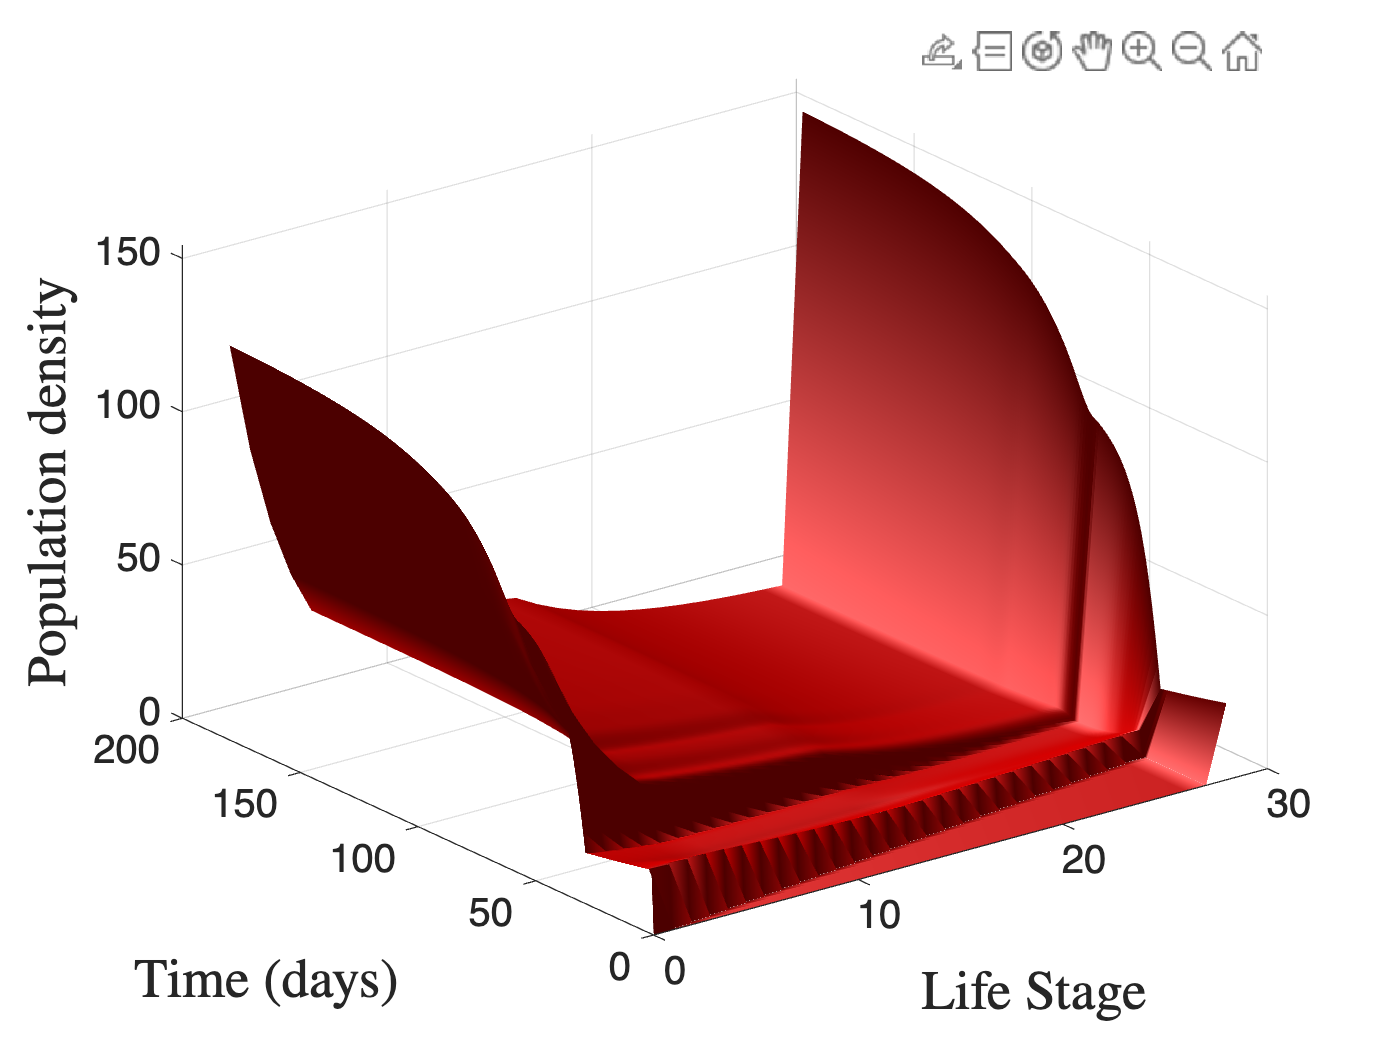

[Time, Stage] = meshgrid(0:MaxN, 0:S);

surf(Stage, Time, DF', ...
    'FaceColor',[1 0 0], ...
    'FaceAlpha',1, ...
    'EdgeAlpha', 0, ...
    'FaceLighting', 'gouraud',...
    'BackFaceLighting', 'reverselit')

ax = gca;
ax.FontSize = 16;

light('Position', [0,1,1])

xlabel('Life Stage', 'Interpreter', 'latex', 'FontSize', 22)
ylabel('Time (days)', 'Interpreter', 'latex', 'FontSize', 22)
zlabel('Population density', 'Interpreter', 'latex', 'FontSize', 22)